filelistPP = ["Position_control_PP_29-Apr-2025_15-52-56.mat", "Position_control_PP_29-Apr-2025_15-57-33.mat", "Position_control_PP_29-Apr-2025_15-59-58.mat", "Position_control_PP_29-Apr-2025_16-05-57.mat", "Position_control_PP_29-Apr-2025_16-06-47.mat", "Position_control_PP_29-Apr-2025_16-08-04.mat", "Position_control_PP_29-Apr-2025_16-15-38.mat", "Position_control_PP_29-Apr-2025_16-19-46.mat", "Position_control_PP_29-Apr-2025_16-21-40.mat", "Position_control_PP_29-Apr-2025_16-27-10.mat", "Position_control_PP_29-Apr-2025_16-42-20.mat", "Position_control_PP_29-Apr-2025_16-47-32.mat", "Position_control_PP_29-Apr-2025_16-51-46.mat", "Position_control_PP_29-Apr-2025_16-53-53.mat", "Position_control_PP_29-Apr-2025_16-56-11.mat", "Position_control_PP_29-Apr-2025_17-06-15.mat", "Position_control_PP_29-Apr-2025_17-07-34.mat", "Position_control_PP_29-Apr-2025_17-09-36.mat", "Position_control_PP_29-Apr-2025_17-12-23.mat", "Position_control_PP_29-Apr-2025_17-24-13.mat", "Position_control_PP_29-Apr-2025_17-27-12.mat", "Position_control_PP_29-Apr-2025_17-36-36.mat", "Position_control_PP_29-Apr-2025_17-44-09.mat", "Position_control_PP_29-Apr-2025_17-52-13.mat", "Position_control_PP_29-Apr-2025_17-54-56.mat", "Position_control_PP_29-Apr-2025_17-57-36.mat", "Position_control_PP_29-Apr-2025_17-59-27.mat", "Position_control_PP_29-Apr-2025_18-02-38.mat", "Position_control_PP_29-Apr-2025_18-04-42.mat", "Position_control_PP_29-Apr-2025_18-07-34.mat", "Position_control_PP_29-Apr-2025_18-09-31.mat", "Position_control_PP_29-Apr-2025_18-15-12.mat", "Position_control_PP_29-Apr-2025_18-17-45.mat", "Position_control_PP_29-Apr-2025_18-21-45.mat", "Position_control_PP_29-Apr-2025_18-22-36.mat", "Position_control_PP_29-Apr-2025_18-25-08.mat", "Position_control_PP_29-Apr-2025_18-28-11.mat", "Position_control_PP_29-Apr-2025_18-31-08.mat", "Position_control_PP_29-Apr-2025_18-34-28.mat", "Position_control_PP_29-Apr-2025_18-35-20.mat", "Position_control_PP_29-Apr-2025_18-36-40.mat", "Position_control_PP_29-Apr-2025_18-39-17.mat", "Position_control_PP_29-Apr-2025_18-49-00.mat", "Position_control_PP_29-Apr-2025_18-51-45.mat", "Position_control_PP_29-Apr-2025_18-54-05.mat", "Position_control_PP_29-Apr-2025_18-55-32.mat", "Position_control_PP_29-Apr-2025_18-57-08.mat", "Position_control_PP_29-Apr-2025_18-59-52.mat"];
filelistFB =["Angle_control_FB_29-Apr-2025_14-39-52.mat", "Angle_control_FB_29-Apr-2025_14-43-14.mat", "Angle_control_FB_29-Apr-2025_14-47-31.mat", "Angle_control_FB_29-Apr-2025_14-49-13.mat", "Angle_control_FB_29-Apr-2025_14-52-22.mat", "Angle_control_FB_29-Apr-2025_14-56-16.mat", "Angle_control_FB_29-Apr-2025_14-59-10.mat", "Angle_control_FB_29-Apr-2025_15-04-08.mat", "Angle_control_FB_29-Apr-2025_15-06-02.mat", "Angle_control_FB_29-Apr-2025_15-09-49.mat", "Angle_control_FB_29-Apr-2025_15-11-09.mat", "Angle_control_FB_29-Apr-2025_15-21-00.mat", "Angle_control_FB_29-Apr-2025_15-25-22.mat", "Angle_control_FB_29-Apr-2025_15-26-51.mat", "Angle_control_FB_29-Apr-2025_15-28-52.mat"];

FB_m0 = "lab6/data/FB/"+filelistFB(1);
FB_m1 = "lab6/data/FB/"+filelistFB(2);
PP_m0 = "lab6/data/PP/"+filelistPP(48);
PP_m1 = "lab6/data/PP/"+filelistPP(47);

exp_list = [FB_m0,FB_m1, PP_m0, PP_m1];
m_id = [0,1,0,1];


omega_stairs = load("lab6\preplan\angle_ref_scenario_freq.mat").x1to34_sparse;

tstart_d=1;
tend_d=1;
do_plots = false;
amp = 15;
% tableofData = [];

m0_PP = {};
m1_PP = {};
m0_FB = {};
m1_FB = {};


for e = 1:4
    data = load(exp_list(e)).data;
    y_ref = data(10+m_id(e),:);
    y = data(2+m_id(e),:);
    time = data(1,:);
    om=resample(omega_stairs{1},time).data;
    slices = sliceTimeSeries(time,om);
    for i = 1:size(slices,2)
        
        omega = slices{i}.f;
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+tstart_d);
        t_end_idx = time2index(focus.t_end-tend_d);
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        y_focus= y(t_start_idx:t_end_idx);
        u_focus= y_ref(t_start_idx:t_end_idx);
        if do_plots
            figure
            subplot(2,2,1)
                plot(t_focus,om_focus)
                title(focus.t_start + "s ->" + focus.t_end + "s")
            subplot(2,2,2)
                plot(t_focus,u_focus)
                title("Voltage")
            subplot(2,2,[3 4])
        end
        [phase, gain, phase_del] = NewSweepAnalysis(t_focus,u_focus, y_focus, omega, do_plots);
        slices{i}.phase = phase;
        slices{i}.gain = gain;
        slices{i}.phase_del = phase_del;
    end
    

    [freqs,phases, gains, phase_dels] = flatten(slices);
    
    exp_temp.freq = freqs;
    exp_temp.phases = phases;
    exp_temp.gains = gains;

    if e == 1
        m0_FB = exp_temp;
    elseif e ==2
         m1_FB = exp_temp;
    elseif e ==3
         m0_PP = exp_temp;
    elseif e ==4
        m1_PP = exp_temp;
    end
end

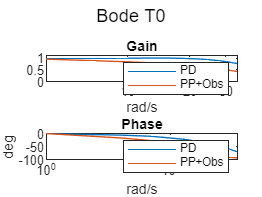

% M0
subplot(2,1,1)

plot(m0_FB.freq,m0_FB.gains)
hold on
plot(m0_PP.freq,m0_PP.gains)
hold off
title("Gain")
sgtitle("Bode T0")
xlabel("rad/s")
ylim([0 1.1])
xscale("log")

legend(["PD", "PP+Obs"])
subplot(2,1,2)
plot(m0_FB.freq,rad2deg(m0_FB.phases))
hold on
plot(m0_PP.freq,rad2deg(m0_PP.phases))
hold off

ylabel("deg")
title("Phase")
xlabel("rad/s")
legend(["PD", "PP+Obs"])
xscale("log")

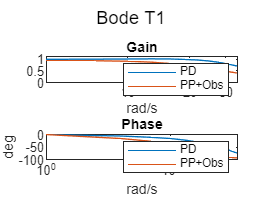

% M1
subplot(2,1,1)

plot(m1_FB.freq,m1_FB.gains)
hold on
plot(m1_PP.freq,m1_PP.gains)
hold off
title("Gain")
sgtitle("Bode T1")
xlabel("rad/s")
ylim([0 1.1])
xscale("log")

legend(["PD", "PP+Obs"])
subplot(2,1,2)
plot(m1_FB.freq,rad2deg(m1_FB.phases))
hold on
plot(m1_PP.freq,rad2deg(m1_PP.phases))
hold off
title("Phase")
xlabel("rad/s")
ylabel("deg")
legend(["PD", "PP+Obs"])
xscale("log")

function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end